Exploring the Logistic Equation, as an example of feedback in a nonlinear system. 

Explore it with a few values of parameter r:

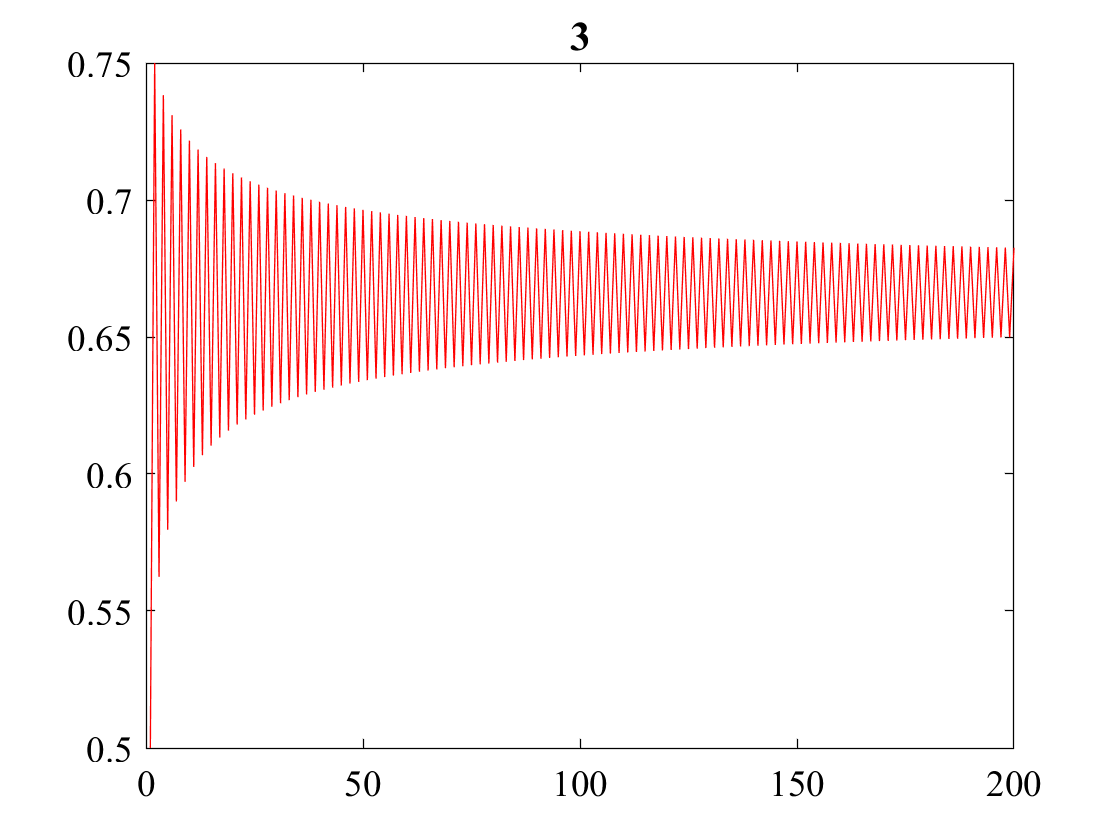

r = 3; % a parameter between [0:4]
x = zeros(1,200);
x(1) = 0.5; % or rand(1); % initial condition
for i=2:length(x)
    x(i) = r * x(i-1) * (1-x(i-1));
end
plot(x);
title(sprintf('r = %f', r));

Is this code efficient? Could we write it without the loop? 

What if we do several r's in parallel: 

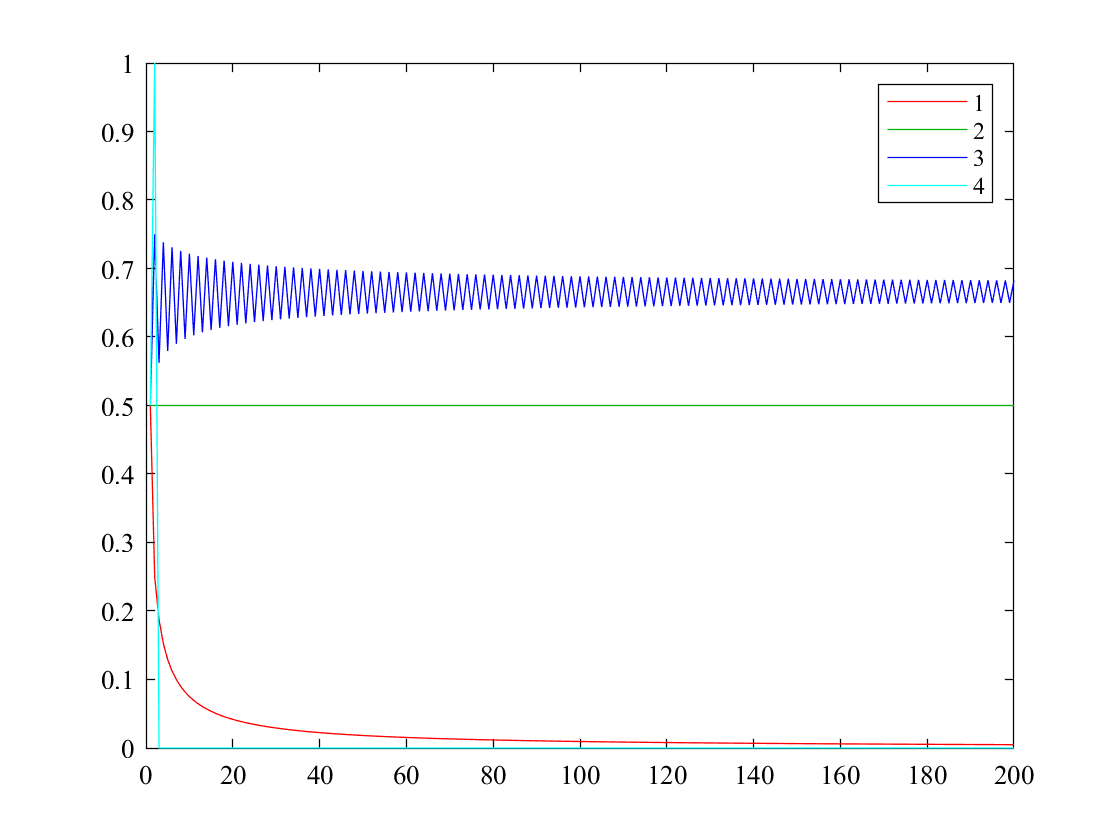

r = 1:4; % a parameter between [0:4]
x = zeros(200,length(r));
x(1,:) = 0.5; % or rand(1); % initial condition
for i=2:length(x)
    x(i,:) = r .* x(i-1,:) .* (1-x(i-1,:));
end
plot(x);
legend(num2str(r'))

What's strange ... why are we doing this? Let's explore more parameter space between 3 and 4:

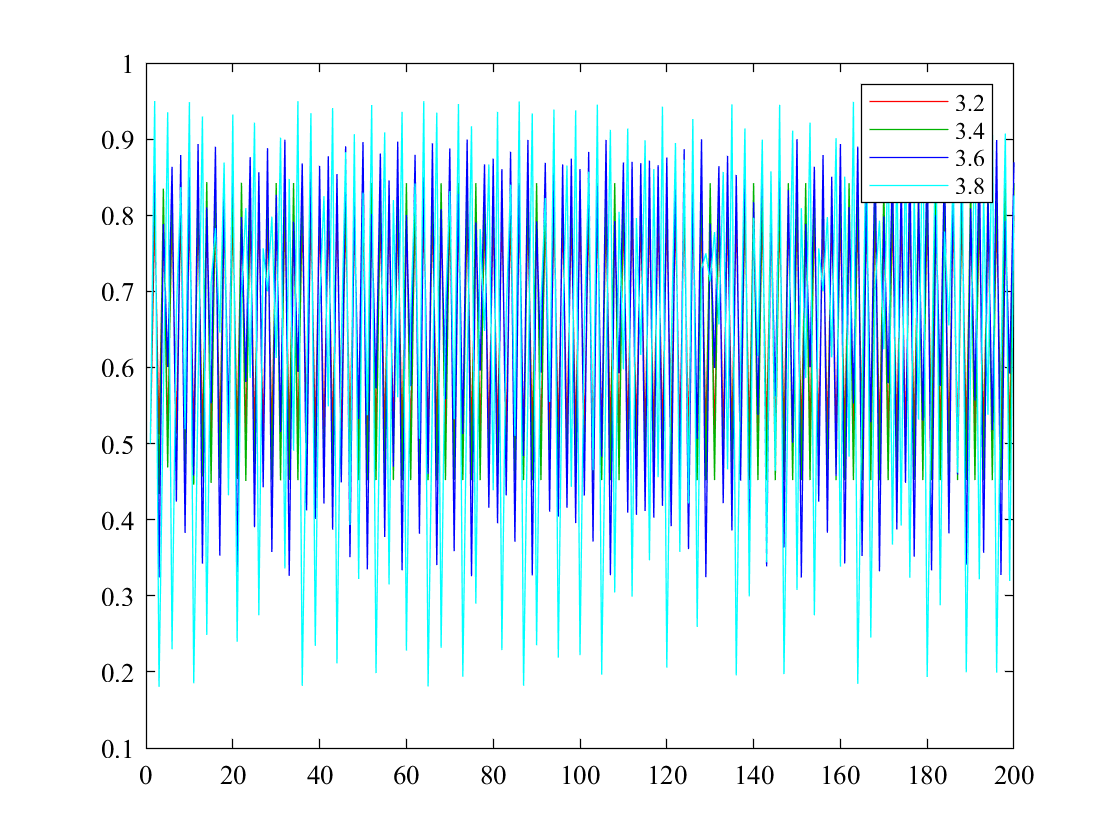

r = 3.2:.2:3.8; % a parameter between [0:4]
x = zeros(200,length(r));
x(1,:) = 0.5; % or rand(1); % initial condition
for i=2:length(x)
    x(i,:) = r .* x(i-1,:) .* (1-x(i-1,:));
end
plot(x);
legend(num2str(r'))